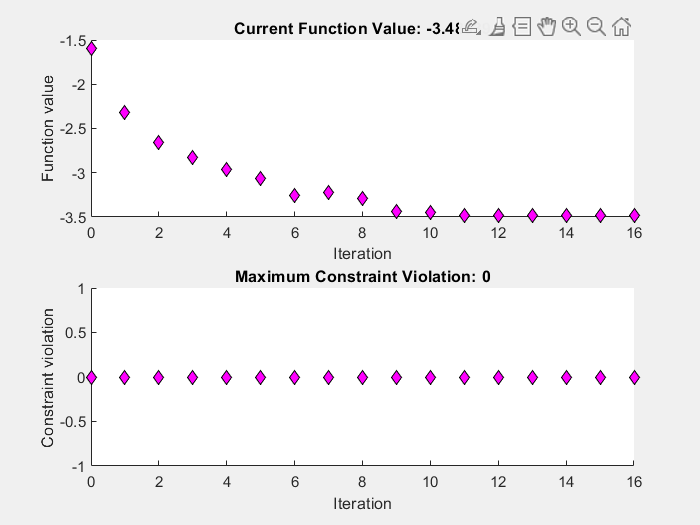


Optimization completed: The relative first-order optimality measure, 4.000518e-09,
is less than options.OptimalityTolerance = 1.000000e-08, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.



% MATLAB Script to Maximize the Magnitude of tau and Visualize the Function

% Clear workspace and command window
clear; clc; close all;

% Define constants (ensure l1 and l5 are positive)
l1 = 1.28;  % Example value for l1
l5 = 1.35;  % Example value for l5

%% Optimization to Maximize ||tau||

% Define the objective function to maximize ||tau||
% Since fmincon minimizes, we minimize the negative norm
objective = @(x) -norm([
    sin(x(1))*(l1*cos(x(3)) - l5*cos(x(2))) - cos(x(1))*(l1*cos(x(3)) - l5*cos(x(2))),
    l5*cos(x(1))*sin(x(2)) - l5*cos(x(2)) - l5*sin(x(1))*sin(x(2)),
    -l1*cos(x(1))*sin(x(3)) - l1*cos(x(3)) + l1*sin(x(1))*sin(x(3))
]);



% Initial guess for [theta1, theta2, theta3] in radians
x0 = [0, pi/4, pi/2];  % A feasible initial guess within the specified bounds

% Define bounds for theta1, theta2, theta3
lb = [-pi/2, 0, pi/4];        % Lower bounds
ub = [ pi/2, pi/2, 3*pi/4];  % Upper bounds

% lb = [-10, -10, -10];        % Lower bounds
% ub = [ 10, 10, 10];  % Upper bounds

% Set optimization options
options = optimoptions('fmincon', ...
    'Algorithm', 'interior-point', ...         % Switched to 'interior-point' for better handling of large-scale problems
    'Display', 'final-detailed', ...           % Show detailed results at the end of optimization
    'MaxIterations', 500, ...                  % Limit the number of iterations to 500
    'MaxFunctionEvaluations', 1e5, ...         % Increase function evaluations to handle complex problems
    'OptimalityTolerance', 1e-8, ...           % Stricter tolerance for optimality
    'StepTolerance', 1e-8, ...                 % Stricter step tolerance
    'ConstraintTolerance', 1e-6, ...           % Add explicit constraint tolerance
    'FiniteDifferenceType', 'central', ...     % Use central differences for gradient approximation for better accuracy
    'FiniteDifferenceStepSize', 1e-5, ...      % Small step size for finite difference approximation
    'HessianApproximation', 'lbfgs', ...       % Approximate the Hessian using L-BFGS for memory efficiency
    'CheckGradients', true, ...                % Enable gradient checking for debugging
    'PlotFcn', {@optimplotfval, @optimplotconstrviolation} ... % Plot function value and constraint violation
    );           % Add a custom output function to monitor progress


% Perform the optimization using fmincon
% No nonlinear constraints, so set them to empty
[x_opt, fval, exitflag, output] = fmincon(objective, x0, [], [], [], [], lb, ub, [], options);


% Check if optimization was successful
if exitflag <= 0
    warning('Optimization did not converge to a solution.');
end

% Extract optimal angles
theta1_opt = x_opt(1);
theta2_opt = x_opt(2);
theta3_opt = x_opt(3);

% Calculate the maximum norm of tau
max_tau_norm = -fval;

% Display the results
fprintf('Optimal Angles (radians):\n');

Optimal Angles (radians):


fprintf('theta1 = %.4f rad (%.2f°)\n', theta1_opt, rad2deg(theta1_opt));

theta1 = -0.7854 rad (-45.00°)


fprintf('theta2 = %.4f rad (%.2f°)\n', theta2_opt, rad2deg(theta2_opt));

theta2 = 0.0000 rad (0.00°)


fprintf('theta3 = %.4f rad (%.2f°)\n', theta3_opt, rad2deg(theta3_opt));

theta3 = 2.3562 rad (135.00°)


fprintf('Maximum ||tau|| = %.4f\n', max_tau_norm);

Maximum ||tau|| = 3.4834



% (Optional) Display the optimal tau vector
tau_opt = [
    sin(theta1_opt)*(l1*cos(theta3_opt) - l5*cos(theta2_opt)) - cos(theta1_opt)*(l1*cos(theta3_opt) - l5*cos(theta2_opt)),
    l5*cos(theta1_opt)*sin(theta2_opt) - l5*cos(theta2_opt) - l5*sin(theta1_opt)*sin(theta2_opt),
    -l1*cos(theta1_opt)*sin(theta3_opt) - l1*cos(theta3_opt) + l1*sin(theta1_opt)*sin(theta3_opt)
];


fprintf('Optimal tau vector:\n');

Optimal tau vector:


fprintf('[%.4f, %.4f, %.4f]\n', tau_opt(1), tau_opt(2), tau_opt(3));

[3.1892, -1.3500, -0.3749]


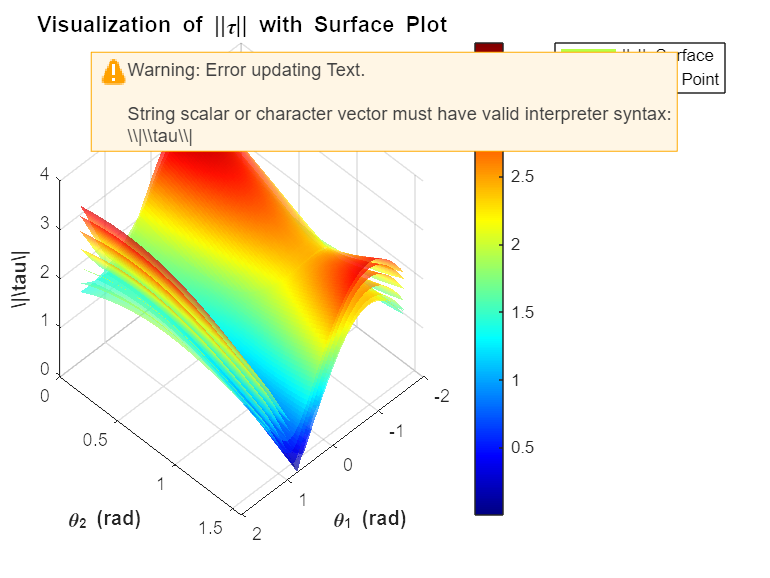


%% Visualization: 3D Scatter Plot with Color Representing ||tau||

% Define the number of sample points for each variable
num_theta1 = 100;
num_theta2 = 100;
num_theta3 = 100;

% Generate a grid of theta1, theta2, theta3 within the specified bounds
theta1_vals = linspace(lb(1), ub(1), num_theta1);
theta2_vals = linspace(lb(2), ub(2), num_theta2);
theta3_vals = linspace(lb(3), ub(3), num_theta3);

% Create a meshgrid for theta1, theta2, theta3
[Theta1, Theta2, Theta3] = ndgrid(theta1_vals, theta2_vals, theta3_vals);

% Reshape the grids into vectors for easy computation
Theta1_vec = Theta1(:);
Theta2_vec = Theta2(:);
Theta3_vec = Theta3(:);

% Preallocate a vector to store ||tau|| values
tau_norm_vec = zeros(size(Theta1_vec));

% Compute ||tau|| for each combination of theta1, theta2, theta3
for i = 1:length(Theta1_vec)
    tau = [
        sin(Theta1_vec(i))*(l1*cos(Theta3_vec(i)) - l5*cos(Theta2_vec(i))) - cos(Theta1_vec(i))*(l1*cos(Theta3_vec(i)) - l5*cos(Theta2_vec(i))),
        l5*cos(Theta1_vec(i))*sin(Theta2_vec(i)) - l5*cos(Theta2_vec(i)) - l5*sin(Theta1_vec(i))*sin(Theta2_vec(i)),
        -l1*cos(Theta1_vec(i))*sin(Theta3_vec(i)) - l1*cos(Theta3_vec(i)) + l1*sin(Theta1_vec(i))*sin(Theta3_vec(i))
    ];


    tau_norm_vec(i) = norm(tau);
end

% Reshape the computed ||tau|| values to match the grid dimensions
tau_norm_grid = reshape(tau_norm_vec, size(Theta1));

% Reshape the computed ||tau|| values to match the grid dimensions
tau_norm_grid = reshape(tau_norm_vec, size(Theta1));

% Create a surface plot with multiple slices
figure('Name', 'Visualization of ||tau|| with Surface Plot', 'NumberTitle', 'off');

% Define more slice indices for better visualization
num_slices = 7; % Number of slices
slice_indices = round(linspace(1, num_theta3, num_slices)); % Evenly spaced slices along theta3

% Plot the slices
for i = 1:length(slice_indices)
    slice_data = tau_norm_grid(:, :, slice_indices(i));
    surf(Theta1(:, :, 1), Theta2(:, :, 1), slice_data, 'FaceAlpha', 0.7, 'EdgeColor', 'none');
    hold on;
end

xlabel('\theta_1 (rad)', 'FontWeight', 'bold');
ylabel('\theta_2 (rad)', 'FontWeight', 'bold');
zlabel('\|\tau\|', 'FontWeight', 'bold');
title('Visualization of ||\tau|| with Surface Plot', 'FontSize', 12, 'FontWeight', 'bold');
colorbar;
colormap('jet');
view(135, 45); % Set a 3D view angle
grid on;

% Highlight the optimal point found by optimization
scatter3(theta1_opt, theta2_opt, max_tau_norm, 100, 'p', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g', 'LineWidth', 1.5);
legend('||\tau|| Surface', 'Optimal Point');
hold off;